load('flow_data.mat')

part a.)

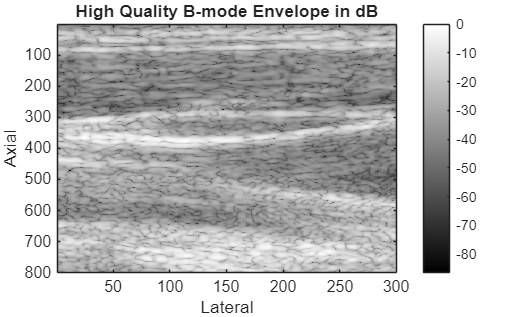

clf;

envh = abs(hilbert(rf_bmode));
envh_db = 20*log10(envh);
norm_envh = envh_db - max(envh_db(:));

figure()
imagesc(norm_envh);
colormap gray
colorbar;
title('High Quality B-mode Envelope in dB');
xlabel('Lateral');
ylabel('Axial');

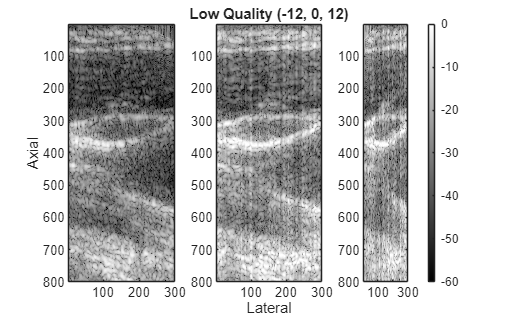


frame = 25;

envl1 = abs(hilbert(rf(:,:,frame,1)));
envl1_db = 20*log10(envl1);
norm_envl1 = envl1_db - max(envl1_db(:));

envl2 = abs(hilbert(rf(:,:,frame,2)));
envl2_db = 20*log10(envl2);
norm_envl2 = envl2_db - max(envl2_db);

envl3 = abs(hilbert(rf(:,:,frame,3)));
envl3_db = 20*log10(envl3);
norm_envl3 = envl3_db - max(envl3_db);

figure()
subplot(1,3,1)
imagesc(norm_envl1);
ylabel('Axial');
colormap gray;
clim([-60 0]);

subplot(1,3,2)
imagesc(norm_envl2);
title('Low Quality (-12, 0, 12)');
xlabel('Lateral');
colormap gray;
clim([-60 0]);

subplot(1,3,3)
imagesc(norm_envl3);
colormap gray;
colorbar;
clim([-60 0]);

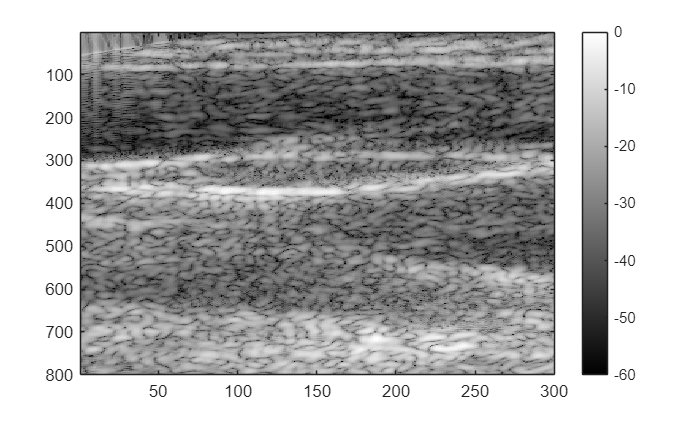


rf_12 = rf(:,:,:,3);

frames = 50;

M(frames) = struct('cdata', [], 'colormap', []);

for j = 1:frames
    env = abs(hilbert(rf_12(:,:,j)));
    env_db = 20*log10(env);
    norm_env = env_db - max(env_db(:));
    
    clf
    imagesc(norm_env);
    colorbar;
    colormap gray;
    clim([-60 0]);
    drawnow limitrate;

    M(j) = getframe;
end

movie(M)